# Problem 1: STSA on a single frame

Required test calls from the handout.

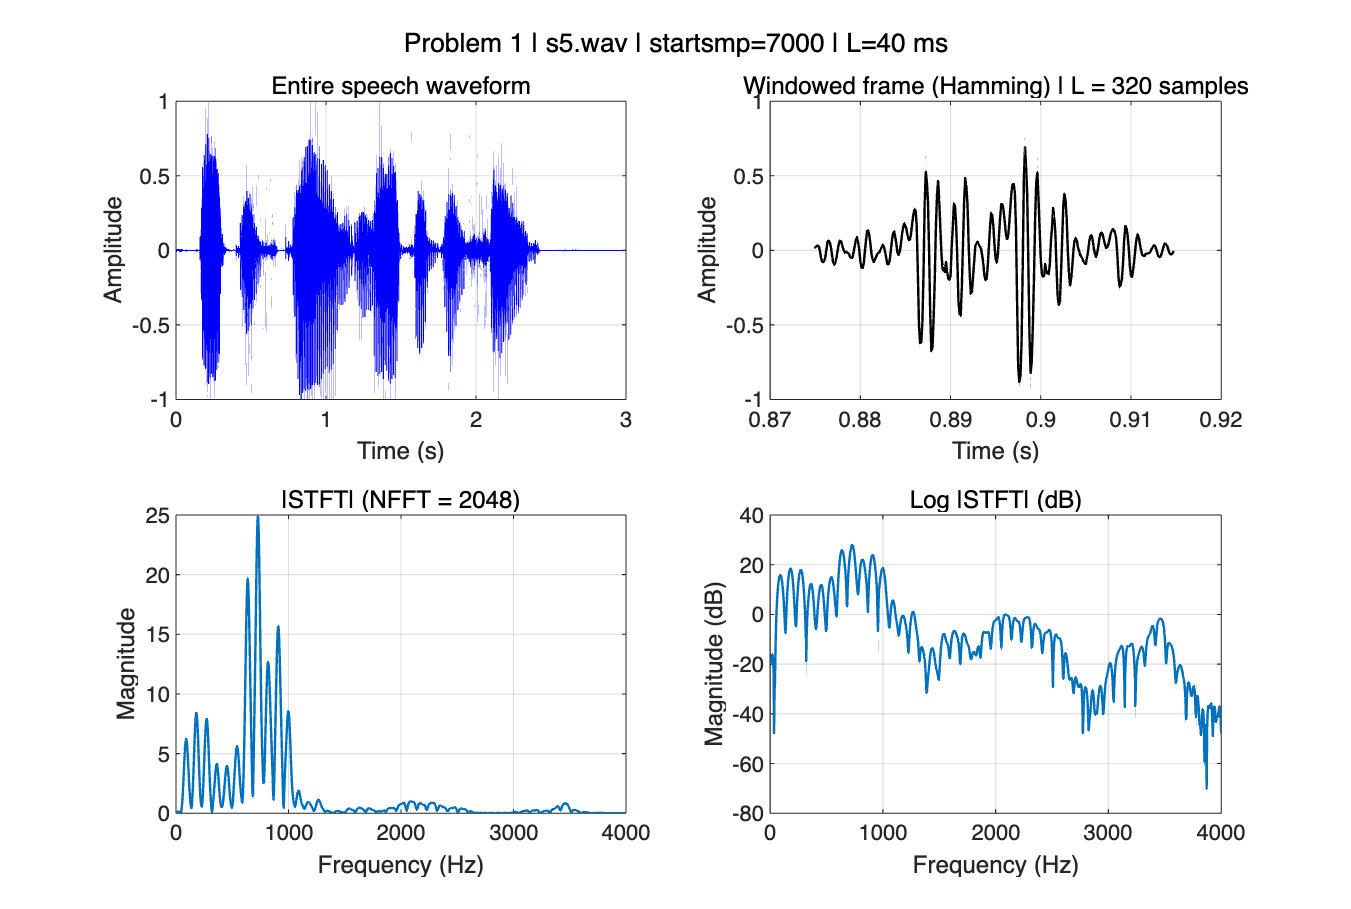

Saved figure: /Users/hwy/Desktop/个人/26春/语音信号处理/lab5/figures/p1_s5_start7000_L40ms.png


STSA_SingleFrame("s5.wav", 7000, 40);

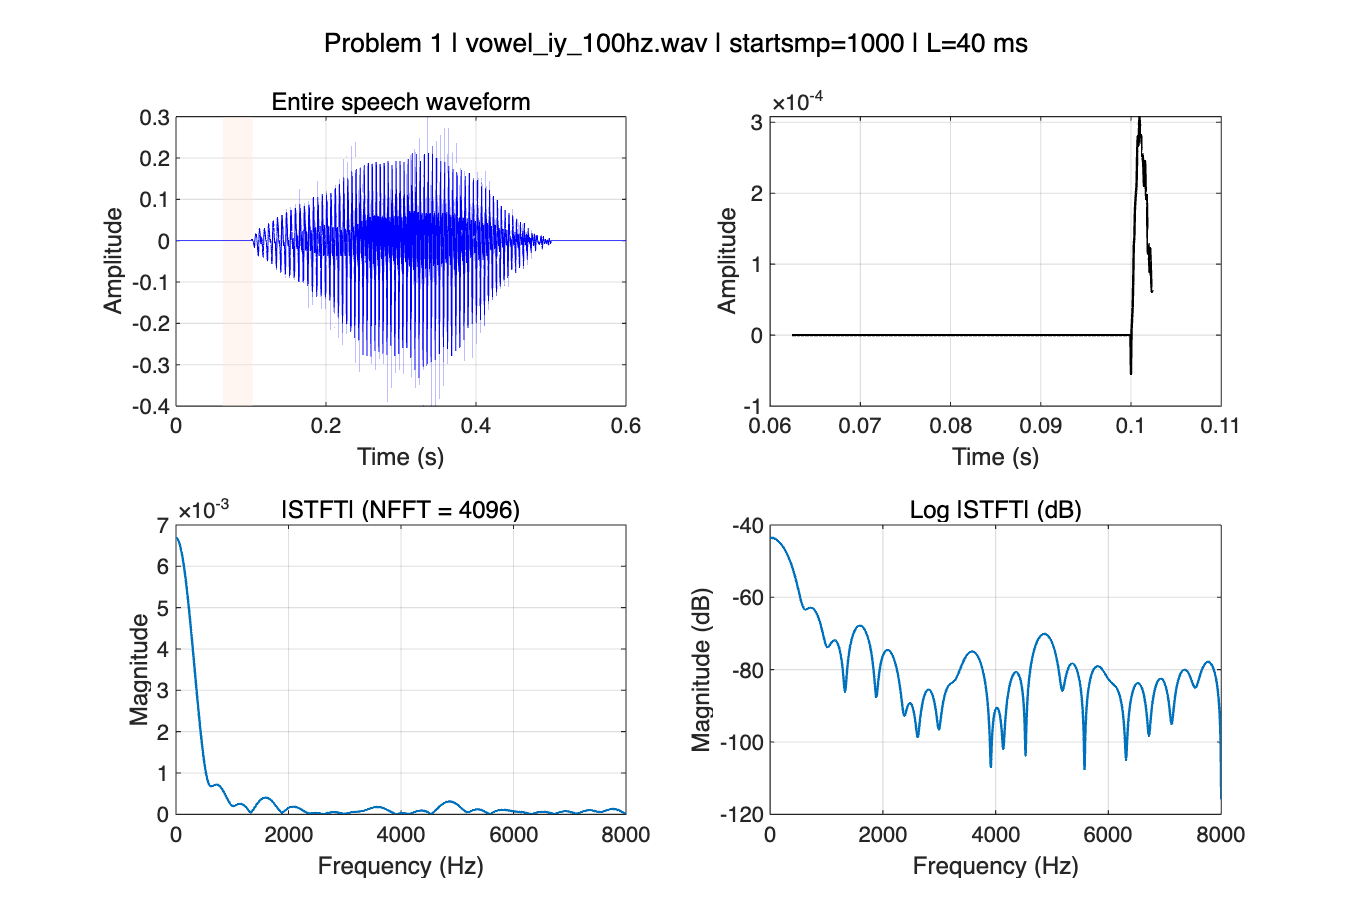

Saved figure: /Users/hwy/Desktop/个人/26春/语音信号处理/lab5/figures/p1_vowel_iy_100hz_start1000_L40ms.png


STSA_SingleFrame("vowel_iy_100hz.wav", 1000, 40);


function figPath = STSA_SingleFrame(filename, startsmp, framelength)
    [x, fs] = audioread(filename);
    if size(x, 2) > 1
        x = mean(x, 2);
    end
    x = x(:);

    startsmp = round(startsmp);
    frameLenSamples = round(framelength * 1e-3 * fs);

    if frameLenSamples < 1
        error("Frame length must be positive.");
    end
    if startsmp < 1 || startsmp > numel(x)
        error("startsmp must be in [1, length(x)].");
    end

    frame = zeros(frameLenSamples, 1);
    endIdx = min(startsmp + frameLenSamples - 1, numel(x));
    validLen = endIdx - startsmp + 1;
    frame(1:validLen) = x(startsmp:endIdx);

    w = hamming(frameLenSamples);
    xw = frame .* w;

    nfft = 2^nextpow2(max(512, 4 * frameLenSamples));
    X = fft(xw, nfft);

    f = (0:nfft/2)' * fs / nfft;
    mag = abs(X(1:nfft/2+1));
    magdB = 20 * log10(mag + eps);

    t = (0:numel(x)-1)' / fs;
    tFrame = ((startsmp-1):(startsmp+frameLenSamples-2))' / fs;

    hFig = figure("Color", "w", "Name", sprintf("Problem1 | %s", filename), ...
        "Position", [100 100 1220 820]);

    subplot(2,2,1);
    plot(t, x, "b");
    hold on;
    yl = ylim;
    patch([tFrame(1) tFrame(end) tFrame(end) tFrame(1)], [yl(1) yl(1) yl(2) yl(2)], ...
        [1 0.9 0.85], "FaceAlpha", 0.35, "EdgeColor", "none");
    uistack(findobj(gca, "Type", "line"), "top");
    grid on;
    xlabel("Time (s)");
    ylabel("Amplitude");
    title("Entire speech waveform", "FontSize", 11);

    subplot(2,2,2);
    plot(tFrame, xw, "k", "LineWidth", 1.1);
    grid on;
    xlabel("Time (s)");
    ylabel("Amplitude");
    title(sprintf("Windowed frame (Hamming) | L = %d samples", frameLenSamples), ...
        "Interpreter", "none", "FontSize", 11);

    subplot(2,2,3);
    plot(f, mag, "LineWidth", 1.1);
    xlim([0 fs/2]);
    grid on;
    xlabel("Frequency (Hz)");
    ylabel("Magnitude");
    title(sprintf("|STFT| (NFFT = %d)", nfft), "FontSize", 11);

    subplot(2,2,4);
    plot(f, magdB, "LineWidth", 1.1);
    xlim([0 fs/2]);
    grid on;
    xlabel("Frequency (Hz)");
    ylabel("Magnitude (dB)");
    title("Log |STFT| (dB)", "FontSize", 11);

    sgtitle(sprintf("Problem 1 | %s | startsmp=%d | L=%d ms", ...
        filename, startsmp, framelength), "Interpreter", "none", "FontSize", 12);

    figPath = saveFigure(hFig, filename, startsmp, framelength);
    disp("Saved figure: " + figPath);
end

function figPath = saveFigure(hFig, filename, startsmp, framelength)
    figDir = fullfile(pwd, "figures");
    if ~exist(figDir, "dir")
        mkdir(figDir);
    end

    [~, base, ~] = fileparts(char(filename));
    figName = sprintf("p1_%s_start%d_L%dms.png", base, round(startsmp), round(framelength));
    figPath = fullfile(figDir, figName);
    exportgraphics(hFig, figPath, "Resolution", 180);
end